clear
clc

syms Theta_1(t) Theta_2(t) Theta_3(t) R_1(t) t
syms r_1 r_1y r_2 r_3
syms theta_1 theta_2 theta_3 
syms V_r omega_1 omega_2 omega_3 
syms a_r alpha_1 alpha_2 alpha_3

Vr_2=0.075

Vr_2 = 0.0750

Vr_3=0.17

Vr_3 = 0.1700

Vr_1y=0.045

Vr_1y = 0.0450

Vtheta_2 = 0

Vomega_2 = 0

Valpha_2 = 0

Fc=sin(Theta_1)*R_1-r_1y;
fc=formula(subs(Fc,[Theta_1, R_1],[theta_1, r_1]));
Fx=-R_1*cos(Theta_1)+r_2*cos(Theta_2)+r_3*cos(Theta_3);
Fx=simplify(Fx,'Steps',5);
fx=formula(subs(Fx,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));
Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5);
fy=formula(subs(Fy,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, r_1]));
DFcDt=diff(Fc);
DFxDt=diff(Fx);
DFyDt=diff(Fy);
F1=formula(subs(DFxDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F2=formula(subs(DFyDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F3=formula(subs(DFcDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
D2FcDt2=diff(DFcDt);
D2FxDt2=diff(DFxDt);
D2FyDt2=diff(DFyDt);
F4=formula(subs(D2FcDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F5=formula(subs(D2FxDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
F6=formula(subs(D2FyDt2,[diff(diff(R_1)),diff(diff(Theta_1)),diff(diff(Theta_2)),diff(diff(Theta_3)),diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[a_r,alpha_1,alpha_2,alpha_3,V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]));
SolR_1=solve(fc,r_1);
SolTheta_1=solve(simplify(subs(fx,r_1,SolR_1),"Steps",15),theta_1);
SolTheta_3=solve(fy-fc,theta_3);
SolTheta_3=SolTheta_3(2);
SolOmega_3=solve(F3-F2,omega_3);
SolOmega_1=solve(F3,omega_1);
SolOmega_1=simplify(SolOmega_1,"Steps",10);
SolV_r=solve(subs(F1,omega_1,SolOmega_1),V_r);
SolV_r=simplify(SolV_r,"Steps",10);
SolAlpha_3=solve(F6-F4,alpha_3);
SolAlpha_3=simplify(SolAlpha_3,"Steps",20);
SolAlpha_1=solve(F4,alpha_1);
SolAlpha_1=simplify(SolAlpha_1,"Steps",20);
SolA_r=solve(subs(F5,alpha_1,SolAlpha_1),a_r);
SolA_r=simplify(SolA_r,"Steps",20);
SolR_1=subs(SolR_1,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolTheta_1=subs(SolTheta_1,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolTheta_3=subs(SolTheta_3,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolV_r=subs(SolV_r,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolOmega_1=subs(SolOmega_1,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolOmega_3=subs(SolOmega_3,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolA_r=subs(SolA_r,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolAlpha_1=subs(SolAlpha_1,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
SolAlpha_3=subs(SolAlpha_3,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
fP(r_1,theta_1,theta_3)=[fc;fx;fy];
fP=subs(fP,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
fP=simplify(fP,'Steps',5);
JacP=jacobian(fP, [r_1,theta_1,theta_3]);
JacInvP=JacP^-1;
fV(V_r,omega_1,omega_3)=[F1;F2;F3];
fV=subs(fV,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
fV=simplify(fV,'Steps',5);
JacV=jacobian(fV, [V_r,omega_1,omega_3]);
JacInvV=JacV^-1;
fA(a_r,alpha_1,alpha_3)=[F4;F5;F6];
fA=subs(fA,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
fA=simplify(fA,'Steps',5);
JacA=jacobian(fA, [a_r,alpha_1,alpha_3]);
JacInvA=JacA^-1; 
f(r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3)=[fc;fx;fy;F1;F2;F3;F4;F5;F6];
f=subs(f,[r_1y,r_2,r_3],[Vr_1y,Vr_2,Vr_3]);
f=simplify(f,'Steps',5);
JacInv=jacobian(f, [r_1,theta_1,theta_3,V_r,omega_1,omega_3,a_r,alpha_1,alpha_3])^-1;


p1=[-0.0997,-0.4684,2.8737,0,0,0,0,0,0];
Vtheta_2=0;
Vomega_2=4;
Valpha_2=3;

Sol=Fanalitica(SolR_1,SolTheta_1,SolTheta_3,SolV_r,SolOmega_1,SolOmega_3,SolA_r,SolAlpha_1,SolAlpha_3,Vtheta_2,Vomega_2,Valpha_2);
[SolSimultaneo,error_NR]=NR_Sistema(f,JacInv,p1,Vtheta_2,Vomega_2,Valpha_2);
[SolConsecutivo,Error_NR_con]= NR_Sistema_extenso(fP,JacInvP,fV,JacInvV,fA,JacInvA,p1,Vtheta_2,Vomega_2,Valpha_2);

Resultados=[Sol;SolSimultaneo;SolConsecutivo]

Resultados =    -0.0997   -0.4684    2.8737   -0.0735    0.3730    1.8300   -0.6129    2.4912    0.4532
   -0.0997   -0.4684    2.8737   -0.0735    0.3730    1.8300   -0.6129    2.4912    0.4532
   -0.0997   -0.4684    2.8737   -0.0735    0.3730    1.8300   -0.6129    2.4912    0.4532


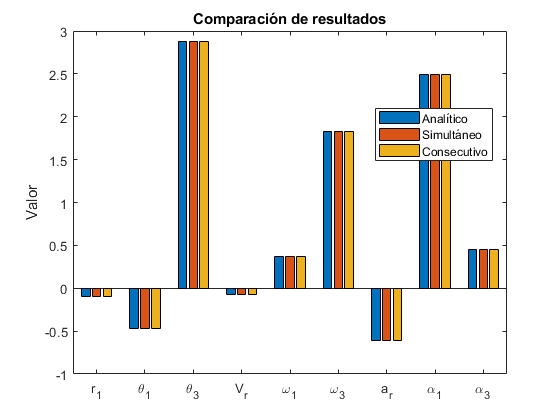


bar([Sol',SolSimultaneo',SolConsecutivo'])
title("Comparación de resultados")
ylabel("Valor")
legend("Analítico","Simultáneo","Consecutivo","location","best")
xticklabels(["r_1","\theta_1","\theta_3","V_r","\omega_1","\omega_3","a_r","\alpha_1","\alpha_3"])

function solAnalitica=Fanalitica(SolR_1,SolTheta_1,SolTheta_3,SolV_r,SolOmega_1,SolOmega_3,SolA_r,SolAlpha_1,SolAlpha_3,Vtheta_2,Vomega_2,Valpha_2)
syms r_1 theta_1 theta_2 theta_3 V_r omega_1 omega_2 omega_3 a_r alpha_1 alpha_2 alpha_3
Vtheta_3=double(subs(SolTheta_3,theta_2,Vtheta_2));
Vtheta_1=double(subs(SolTheta_1,[theta_2,theta_3],[Vtheta_2,Vtheta_3]));
Vr_1=double(subs(SolR_1,theta_1,Vtheta_1));
Vomega_3=double(subs(SolOmega_3,[theta_2,theta_3,omega_2],[Vtheta_2,Vtheta_3,Vomega_2]));
Vv_r=double(subs(SolV_r,[theta_1,theta_2,theta_3,omega_2,omega_3],[Vtheta_1,Vtheta_2,Vtheta_3,Vomega_2,Vomega_3]));
Vomega_1=double(subs(SolOmega_1,[r_1,theta_1,V_r],[Vr_1,Vtheta_1,Vv_r]));
Valpha_3=double(subs(SolAlpha_3,[theta_2,theta_3,omega_2,omega_3,alpha_2],[Vtheta_2,Vtheta_3,Vomega_2,Vomega_3,Valpha_2]));
Va_r=double(subs(SolA_r,[r_1,theta_1,theta_2,theta_3,omega_1,omega_2,omega_3,alpha_2,alpha_3],[Vr_1,Vtheta_1,Vtheta_2,Vtheta_3,Vomega_1,Vomega_2,Vomega_3,Valpha_2,Valpha_3]));
Valpha_1=double(subs(SolAlpha_1,[r_1,theta_1,V_r,omega_1,a_r],[Vr_1,Vtheta_1,Vv_r,Vomega_1,Va_r]));
solAnalitica=[Vr_1,Vtheta_1,Vtheta_3,Vv_r,Vomega_1,Vomega_3,Va_r,Valpha_1,Valpha_3];
end


function [Sol,Error]= NR_Sistema(F,FJacInv,Pi,Ftheta_2,Fomega_2,Falpha_2)
syms omega_2 theta_2 alpha_2 
f=subs(F,[theta_2,omega_2,alpha_2],[Ftheta_2,Fomega_2,Falpha_2]);
JacInv=subs(FJacInv,[theta_2,omega_2,alpha_2],[Ftheta_2,Fomega_2,Falpha_2]);
p=Pi';
ValoresNR(1,:)=p';
iteraciones=50;
for i=1:iteraciones
    p=double(p-JacInv(p(1),p(2),p(3),p(4),p(5),p(6),p(7),p(8),p(9))*f(p(1),p(2),p(3),p(4),p(5),p(6),p(7),p(8),p(9)));
    ValoresNR(i+1,:)=double(p)';
    ErrorNR(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.000001
        break;
    end
end
    Error=NormErrorNR(end);
    Sol=p';
end

function [Sol,Error]= NR_Sistema_extenso(fP,JacInvP,fV,JacInvV,fA,JacInvA,Pi,Vtheta_2,Vomega_2,Valpha_2)
syms  r_1y r_1 r_2 r_3 theta_3 theta_2 theta_1 V_r omega_1 omega_2 omega_3 a_r alpha_1 alpha_2 alpha_3
fP=subs(fP,theta_2,Vtheta_2);
PiP=[Pi(1),Pi(2),Pi(3)]';
ValoresNR(1,:)=PiP';
iteraciones=50;
for i=1:iteraciones
    PiP=double(PiP-JacInvP(PiP(1),PiP(2),PiP(3))*fP(PiP(1),PiP(2),PiP(3)));
    ValoresNR(i+1,:)=double(PiP)';
    ErrorNR_P(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR_P(i)=norm(ErrorNR_P(i,:));
     if NormErrorNR_P(i)<0.000001
        break;
    end
end
SolPosNR=PiP;
ErrorP=NormErrorNR_P(end);
fV=subs(fV,[theta_2,r_1,theta_1,theta_3,omega_2],[Vtheta_2,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2]);
JacInvV=subs(JacInvV,[theta_2,r_1,theta_1,theta_3,omega_2],[Vtheta_2,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2]);
PiV=[Pi(4),Pi(5),Pi(6)]';
ValoresVNR(1,:)=PiV';
iteraciones=50;
for i=1:iteraciones
    PiV=double(PiV-JacInvV(PiV(1),PiV(2),PiV(3))*fV(PiV(1),PiV(2),PiV(3)));
    ValoresVNR(i+1,:)=double(PiV)';
    ErrorNR_V(i,:)=abs(ValoresVNR(i,:)-ValoresVNR(i+1,:));
    NormErrorNR_V(i)=norm(ErrorNR_V(i,:));
     if NormErrorNR_V(i)<0.000001
        break;
    end
end
SolVelNR=double(PiV);
ErrorV=NormErrorNR_V(end);
fA=subs(fA,[theta_2,r_1,theta_1,theta_3,omega_2,V_r,omega_1,omega_3,alpha_2],[Vtheta_2,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2,SolVelNR(1),SolVelNR(2),SolVelNR(3),Valpha_2]);
JacInvA=subs(JacInvA,[theta_2,r_1,theta_1,theta_3,omega_2,V_r,omega_1,omega_3,alpha_2],[Vtheta_2,SolPosNR(1),SolPosNR(2),SolPosNR(3),Vomega_2,SolVelNR(1),SolVelNR(2),SolVelNR(3),Valpha_2]);
PiA=[Pi(7),Pi(8),Pi(9)]';
ValoresVNR(1,:)=PiA';
iteraciones=50;
for i=1:iteraciones
    PiA=double(PiA-JacInvA(PiA(1),PiA(2),PiA(3))*fA(PiA(1),PiA(2),PiA(3)));
    ValoresVNR(i+1,:)=double(PiA)';
    ErrorNR_A(i,:)=abs(ValoresVNR(i,:)-ValoresVNR(i+1,:));
    NormErrorNR_A(i)=norm(ErrorNR_A(i,:));
     if NormErrorNR_A(i)<0.000001
        break;
    end
end
SolAceNR=double(PiA);
ErrorA=NormErrorNR_A(end);
Sol=[SolPosNR',SolVelNR',SolAceNR'];
Error=norm([ErrorP,ErrorV,ErrorA]);
end

